% Constants
    m = 5.59; %Mass of chaff fibre (grams)
    g = 9.81; %accleration due to gravity (ms^2)
    rho = 0.7364; %atmospheric density (assumed constant) (kg/m^3)
    aOne = 1.5; %Distance impact factor
    fValue = 0.1;  %Proportionality coefficient
    dt = 2.1; %Time step
    maxTime = 410; %Final time of the simulation
    numberOfChaff = 1100; %Number of chaff fibres
    sizeOfChaff = 15; %Size of chaff on the graph
    V = 30; %Size of chaff on the graph
    radius = 0.03; %Radius of chaff
    aircraftMass = 8500;     % kg
    load_factor = 1.3;           % dimensionless
    aircraftWingspan = 25;                      % m (wingspan)
    aircraftSpeed = 800;             % m/s
    radarWavelength = 0.11;       % Wavelength in meters (example: 10 cm)


Only for random distributions:

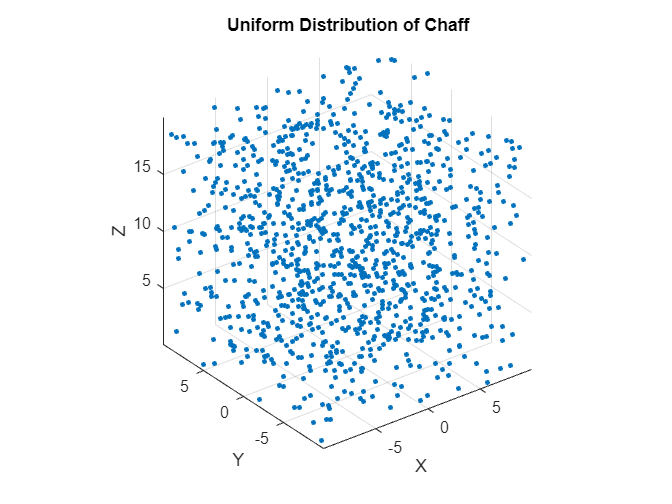

    Strip_Spacing = 10;
    Widths = 0.05;
    Lengths = 2;
    distributionType = "uniformDistribution";
     

meanLength = radarWavelength / 2; % Mean chaff length
% Orientation parameters
azimuthRange = [0, 2*pi]; % Azimuth angles (radians)
elevationRange = [0, pi]; % Elevation angles (radians)

switch distributionType
    case 'randomDistribution2D'
        randomDistribution2D(numberOfChaff, Strip_Spacing, Widths, Lengths);
    case 'randomDistribution3D'
        randomDistribution3D(numberOfChaff, Strip_Spacing, Widths, Lengths);
    case 'uniformDistribution'
        uniformDistribution(numberOfChaff);
    case 'gaussianDistribution'
        gaussianDistribution(numberOfChaff,meanLength,azimuthRange,elevationRange);
    case 'monteCarloDistribution'
        monteCarloDistribution(numberOfChaff,meanLength,azimuthRange,elevationRange);
    case 'normalDistributionOfChaffLengths'
        normalDistributionOfChaffLengths(numberOfChaff,meanLength);
    case 'sixDOF'
        sixDOF(m,g,rho,aOne,fValue,dt,maxTime,numberOfChaff,sizeOfChaff,V,radius,aircraftMass,load_factor,aircraftWingspan,aircraftSpeed)
    case 'aircraftVortices'
        aircraftVortices(aircraftMass,load_factor,g,rho,aircraftWingspan,aircraftSpeed)
    case 'highSpeedReleaseOfChaff'
        highSpeedReleaseOfChaff(rho,Lengths,g,m) 
end

    function sixDOF(m,g,rho,aOne,fValue,dt,maxTime,numberOfChaff,sizeOfChaff,V,radius,aircraftMass,load_factor,aircraftWingspan,aircraftSpeed)
%Code to model 6DOF primarily using the paper: 
%https://www.researchgate.net/publication/327064480_Experimental_and_numerical_study_of_chaff_cloud_kinetic_performance_under_the_impact_of_high_speed_airflow
%implementation of RCS from: 'Absoprtion and scattering of light by small
%particles', Bohren and Huffman (1988)
main(m,g,rho,aOne,fValue,dt,maxTime,numberOfChaff,sizeOfChaff,V,radius,aircraftMass,load_factor,aircraftWingspan,aircraftSpeed)
function main(m,g,rho,aOne,fValue,dt,maxTime,numberOfChaff,sizeOfChaff,V,radius,aircraftMass,load_factor,aircraftWingspan,aircraftSpeed)
    % Initialising parameters
    theta = pi/2; %pitch angle (radians)
    Psi_s = pi/3; %yaw? angle (radians)
    zeta = pi; % (radians)
    psi = pi/2; %(radians)
    E_wave = [1, 0, 0]; %Incident EM wave direction coming from x-direction

    % Unit vectors
    n_d = [(-sin(zeta)*cos(psi)), (cos(zeta)), (sin(zeta)*sin(psi))]; %unit vector of 
    n_v = [(cos(theta)*cos(psi)), sin(theta), (-cos(theta)*sin(psi))]; %unit vector of velocity 
    n_y = cross(n_v, cross(n_v,n_d) * dot(n_v,n_d)); %unit vector of lift 
    n_y = n_y / norm(n_y);

    gamma_s = -asin(((n_v(3)*n_y(1)) - (n_v(1)*n_y(3))*n_y(2)) / (sqrt((n_v(1))^2+(n_v(3))^2) * abs(n_y(2)))); % roll angle (radians)ans)

    S = 4*pi*radius^2; %area of chaff (m^2) %want to treat like a sphere

    steps = maxTime / dt;

    rcore = 0.5;                 % vortex core radius [m]
    % Lift and circulation
    L = load_factor * aircraftMass * g;
    Gamma = L / (rho * aircraftWingspan * aircraftSpeed);  % Circulation [m^2/s]

    % Example: two vortices
    vortex_start_1 = [-2E8, 0, 0]; % left wingtip
    vortex_end_1   = [-2E8, 0, -10E5]; % trailing downwards behind aircraft
    vortex_start_2 = [2E8, 0, 0];  % right wingtip
    vortex_end_2   = [2E8, 0, -10E5];% left and right wingtip
    Gamma_j = [-Gamma, Gamma];

    % Call the main function
    [inci_array, rcs_array, rcs_normalized] = kinematic_equations(gamma_s, aOne, fValue, 0.52, 0.82, dt, maxTime, m, g, numberOfChaff, rho, S, sizeOfChaff, V, steps, zeta, psi, E_wave, radius,Gamma_j,vortex_start_1,vortex_end_1,vortex_start_2,vortex_end_2);

    % Plot RCS vs Angle
    figure;
    plot(rad2deg(inci_array), rcs_normalized, 'o');
    xlabel('Scattering Angle (degrees)');
    ylabel('Radar Cross Section (RCS)');
    title('RCS vs Scattering Angle');
    grid on;
end

% Subfunction 1
function [cX, cY] = calculateAerodynamicInterferenceImpactFactors(aOne, fValue, cXPrime, cYPrime)  %Function calculates cX and cY due to the constants f and a1 from paper
    cX = cXPrime * (1 - aOne);
    cY = cYPrime * fValue * (1 - aOne);
    %a1 is distance impact factor and f is proportionality coefficient
end

% Subfunction 2
function [inci_array, rcs_array, rcs_normalized] = kinematic_equations(gamma_s, aOne, fValue, cXPrime, cYPrime, dt, maxTime, m, g, numberOfChaff, rho, S, sizeOfChaff, V, steps, zeta, psi, E_wave, radius,Gamma_j,vortex_start_1,vortex_end_1,vortex_start_2,vortex_end_2)

    [cX, cY] = calculateAerodynamicInterferenceImpactFactors(aOne, fValue, cXPrime, cYPrime);
    xValues = [];
    yValues = [];
    zValues = [];

    inci_array = zeros(1, numberOfChaff);
    rcs_array = zeros(1, numberOfChaff);

    for i = 1:numberOfChaff
        x = rand()*50; y = rand()*50; z = rand()*50;
        theta = pi; 
        PsiS = pi;
        V_local = V;
        zeta_i = 2*pi*rand();  % Random initial zeta for each chaff
        psi_i = 2*pi*rand();

        for t = 0:dt:maxTime
            n_d = [(-sin(zeta)*cos(psi)), cos(zeta), sin(zeta)*sin(psi)];
            n_v = [(cos(theta)*cos(psi)), sin(theta), (-cos(theta)*sin(psi))];
            n_y = cross(n_v, cross(n_v,n_d) * dot(n_v,n_d));
            n_y = n_y / norm(n_y);

            gamma_s = -asin(((n_v(3)*n_y(1)) - (n_v(1)*n_y(3))*n_y(2)) / ...
                (sqrt(n_v(1)^2 + n_v(3)^2) * abs(n_y(2))));

            X = 0.5 * cX * rho * V_local^2 * S; %Calculates drag
            Y = 0.5 * cY * rho * V_local^2 * S; %Calculates lift

            dV = ((-X - m*g*sin(theta))/m)*dt; %Change in velocity at each time step
            dTheta = ((Y*cos(gamma_s) - m*g*cos(theta))/(m*V_local))*dt; %Change in theta at each time step
            dPsiS = ((-Y*sin(gamma_s))/(m*V_local*cos(theta)))*dt; %Change in Psi at each time step

            V_local = max(1, min(300, V_local + dV));  % clamp velocity and update the value
            theta = theta + dTheta; %Update the theta value
            PsiS = PsiS + dPsiS; %update the psi value
            r_chaff = [x, y, z];
            v1 = vortex_induced_velocity_3D(r_chaff, vortex_start_1, vortex_end_1, Gamma_j(1));
            v2 = vortex_induced_velocity_3D(r_chaff, vortex_start_2, vortex_end_2, Gamma_j(2));
            v_ind_total = v1 + v2;
            %Uses these new values of V, theta and Psi to find the change in the coordinate

            dx = (V_local * cos(theta) * cos(PsiS) +v_ind_total(1))* dt;
            dy = (V_local * sin(theta)+v_ind_total(2) )* dt;
            dz = (-V_local * cos(theta) * sin(PsiS)+v_ind_total(3)) * dt;

            x = x + dx;
            y = y + dy;
            z = z + dz;
        end

        % Store coordinates
        xValues(end+1) = x;
        yValues(end+1) = y;
        zValues(end+1) = z;

        % Use final position to compute n_d direction
        positionVec = [x, y, z];
        if norm(positionVec) == 0
            n_d = [1, 0, 0]; % fallback to E_wave direction
        else
            n_d = positionVec / norm(positionVec);
        end

        % Compute scattering angle
        inci = acos((dot(E_wave, n_d) / norm(E_wave)*norm(n_d)));


        % RCS calculation
        rcs = pi * (radius)^2 * sin(inci);

        inci_array(i) = inci; %store the values for incident angle
        rcs_array(i) = rcs; %store the values for rcs

        % Normalize RCS 
        lambda = 5e-2; % Example wavelength (1.5cm) - adjust for desiredS radar
        rcs_normalized = rcs_array / (lambda^2);% Normalize by wavelength squared
    end

    % 3D scatter plot
    figure;
    scatter3(xValues, yValues, zValues, sizeOfChaff, 'filled');
    title('Chaff Trajectory');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    grid on;
end

%Calculated induced velocity due to vortices
function v_ind = vortex_induced_velocity_3D(r, vortex_start, vortex_end, Gamma)

    epsilon = 1e-6; % To prevent singularity

    R1 = r - vortex_start;
    R2 = r - vortex_end;
    R0 = vortex_end - vortex_start;

    cross_R1_R2 = cross(R1, R2);
    norm_cross = norm(cross_R1_R2)^2;

    if norm_cross < epsilon
        v_ind = [0, 0, 0];
        return;
    end

    numerator = dot(R0, (R1 ./ norm(R1) - R2 ./ norm(R2)));
    v_ind = (Gamma / (4 * pi * norm_cross)) * cross_R1_R2 * numerator;
end
    end

    function normalDistributionOfChaffLengths(numberOfChaff,meanLength)
    stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
    minLength = 0.01;        % Minimum chaff length (1 cm)
    %% Generate Chaff Lengths
    % Create chaff lengths using a normal distribution and truncate at minLength
    chaffLengths = meanLength + stdDev * randn(numberOfChaff, 1);
    chaffLengths(chaffLengths < minLength) = minLength;
    % Visualise chaff length distribution
    figure;
    histogram(chaffLengths, 30, 'FaceColor', 'b', 'EdgeColor', 'k');
    title('Chaff Length Distribution');
    xlabel('Chaff Length (m)');
    ylabel('Frequency');
    grid on;
    end

    function monteCarloDistribution(numberOfChaff,meanLength,azimuthRange,elevationRange)
    stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
    minLength = 0.01;        % Minimum chaff length (1 cm)
    %% Generate Chaff Lengths
    % Create chaff lengths using a normal distribution and truncate at minLength
    chaffLengths = meanLength + stdDev * randn(numberOfChaff, 1);
    chaffLengths(chaffLengths < minLength) = minLength;
    % Monte Carlo bounds for positions
    xBounds = [-10, 10]; 
    yBounds = [-10, 10];
    zBounds = [0, 20];
    % Generate Monte Carlo positions
    xMC = xBounds(1) + (xBounds(2) - xBounds(1)) * rand(numberOfChaff, 1);
    yMC = yBounds(1) + (yBounds(2) - yBounds(1)) * rand(numberOfChaff, 1);
    zMC = zBounds(1) + (zBounds(2) - zBounds(1)) * rand(numberOfChaff, 1);
    % Generate random orientations for Monte Carlo
    azimuthMC = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numberOfChaff, 1);
    elevationMC = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numberOfChaff, 1);
    % Convert orientations to vector components
    uMC = cos(azimuthMC) .* sin(elevationMC) .* chaffLengths;
    vMC = sin(azimuthMC) .* sin(elevationMC) .* chaffLengths;
    wMC = cos(elevationMC) .* chaffLengths; 
    % Visualise Monte Carlo distribution with orientation
    figure;
    scatter3(xMC, yMC, zMC, 10, 'filled', 'MarkerFaceColor', [0, 0.5, 1]);
    hold on;
    quiver3(xMC, yMC, zMC, uMC, vMC, wMC, 0.5, 'Color', 'r', 'LineWidth', 1);
    hold off;
    title('Monte Carlo Chaff Distribution with Orientation Vectors');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    legend({'Chaff Positions', 'Orientation Vectors'}, 'Location', 'Best');
    grid on; axis equal;
    end

    function gaussianDistribution(numberOfChaff,meanLength,azimuthRange,elevationRange)
    stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
    minLength = 0.01;        % Minimum chaff length (1 cm)
    %% Generate Chaff Lengths
    % Create chaff lengths using a normal distribution and truncate at minLength
    chaffLengths = meanLength + stdDev * randn(numberOfChaff, 1);
    chaffLengths(chaffLengths < minLength) = minLength;
    %% Gaussian Distribution with Orientation
    mu = [0, 0, 10]; % Mean position (center at [0, 0, 10])
    sigma = [5, 5, 2]; % Standard deviations in X, Y, Z directions
    % Generate Gaussian positions
    xGaussian = mu(1) + sigma(1) * randn(numberOfChaff, 1);
    yGaussian = mu(2) + sigma(2) * randn(numberOfChaff, 1);
    zGaussian = mu(3) + sigma(3) * randn(numberOfChaff, 1);
    % Generate random orientations for Gaussian
    azimuthGaussian = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numberOfChaff, 1);
    elevationGaussian = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numberOfChaff, 1);
    % Convert orientations to vector components
    uGaussian = cos(azimuthGaussian) .* sin(elevationGaussian) .* chaffLengths;
    vGaussian = sin(azimuthGaussian) .* sin(elevationGaussian) .* chaffLengths;
    wGaussian = cos(elevationGaussian) .* chaffLengths;
    % Visualise Gaussian distribution with orientation
    figure;
    scatter3(xGaussian, yGaussian, zGaussian, 10, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
    hold on;
    quiver3(xGaussian, yGaussian, zGaussian, uGaussian, vGaussian, wGaussian, 0.5, 'Color', 'm', 'LineWidth', 1);
    hold off;
    title('Gaussian Chaff Distribution with Orientation Vectors');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    legend({'Chaff Positions', 'Orientation Vectors'}, 'Location', 'Best');
    grid on; axis equal;
    end

    function uniformDistribution(numberOfChaff)
    % Uniform Distribution Bounds
    xBounds = [-10, 10];
    yBounds = [-10, 10];
    zBounds = [0, 20];
    %% Uniform Distribution
    % Generate uniform distribution
    xUniform = xBounds(1) + (xBounds(2) - xBounds(1)) * rand(numberOfChaff, 1);
    yUniform = yBounds(1) + (yBounds(2) - yBounds(1)) * rand(numberOfChaff, 1);
    zUniform = zBounds(1) + (zBounds(2) - zBounds(1)) * rand(numberOfChaff, 1);

    % Visualise
    figure;
    scatter3(xUniform, yUniform, zUniform, 10, 'filled');
    title('Uniform Distribution of Chaff');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    grid on; axis equal;
    end
    
    function randomDistribution2D(numberOfChaff, Strip_Spacing, Widths, Lengths)
    Size_X = 1.5;
    Size_Y = 2;
    Size_Z = 1;
    Scaled_Unit = 1;
    %Defines a 3D vector space
    V = @(x,y,z)[x,y,z];
    %Calls function to create geometry of the chaff strips
    geometry = setupGeometry(numberOfChaff, Strip_Spacing, Widths, Lengths, Size_X, Size_Y, Size_Z, Scaled_Unit,V);

    positions = geometry(1:4:end,:); %Defines the positions of the chaff
    neighbour_range = 2* Strip_Spacing; %Defines the nearest neighbour range
    density = zeros(numberOfChaff,1); %Defines the density matrix

    for i = 1:numberOfChaff %For loop repeating for the number of fibres
    distances = sqrt(sum((positions - positions(i,:)).^2,2)); %Calculates the distance between one particle and the other particles.
    density(i) = sum(distances < neighbour_range)-1; %Calculates the density of chaff fibres within the nearest neighbour range
    end

    density_normalised = (density - min(density)) / (max(density) - min(density)); %Normalises the density
    cmap = jet(256); %Creates a colour map
    colormap(cmap);
    figure;
    hold on;
    for i = 1:size(geometry, 1) / 4 %Repeats over geometry/4 as this is the number of fibres as each fibre has 4 points
    strip = geometry((i-1)*4+1:i*4,:); %Stores the geometry of the chaff
    color_idx = round(density_normalised(i)*255) +1; %Creates a colour index depending on the density
    line_color = cmap(color_idx,:); %Changes the line colour due to the colour index
    plot(strip(:,1),strip(:,2), '-','Color',line_color,'LineWidth',1); %Plots each chaff
    end
    title('Chaff Cloud Distribution'); %Defines title and axis label
    xlabel('X Position (Scaled Units)');
    ylabel('Y Position (Scaled Units)');
    colorbar;
    hold off;
        function strips = setupGeometry(numberOfChaff, Strip_Spacing, Widths, Lengths, Size_X, Size_Y, Size_Z, Scaled_Unit,V) %Creates a funciton that calculates the geometry of the chaff fibres
    strips = [];
    for i = 1:numberOfChaff %Iterates through the number of strips
        x = randi([0, 2 * Strip_Spacing * Size_X]) - Strip_Spacing * Size_X; %Defines the x coordinate
        y = randi([0, 2 * Strip_Spacing * Size_Y]) - Strip_Spacing * Size_Y; %Defines the y cooridinate
        z = randi([0, 2 * Strip_Spacing * Size_Z]) - Strip_Spacing * Size_Z; %Defines the z coordinate
        ang = randi([0,360]);

        p1 = V(x,y,z) * Scaled_Unit; %Creates the first vortex coordinate
        p2 = V(x + Widths * sind(ang), y-Widths * cosd(ang), z) * Scaled_Unit; %Creates the second vortex coordinate
        p3 = V(x + Widths * sind(ang) + Lengths *cosd(ang), y-Widths * cosd(ang) + Lengths * sind(ang), z) * Scaled_Unit; %Creates the third vortex coordinate
        p4 = V(x + Lengths * cosd(ang), y+Lengths * sind(ang), z) * Scaled_Unit; %Creates the fourth vortex coordinate

        strip = [p1; p2; p3; p4]; %Compiles all coordinates of fibre
        strips = [strips; strip]; %Appends coordinates to the strip array
    end
end
    end

    function randomDistribution3D(numberOfChaff, Strip_Spacing, Widths, Lengths)
    Size_X = 1.5;
    Size_Y = 2;
    Size_Z = 1;
    Scaled_Unit = 1;
    %Defines a 3D vector space
    V = @(x,y,z)[x,y,z];
    %Calls function to create geometry of the chaff strips
    geometry3D = setupGeometry3D(numberOfChaff, Strip_Spacing, Widths, Lengths, Size_X, Size_Y, Size_Z, Scaled_Unit,V);
    figure;
    hold on;
    for i = 1:size(geometry3D, 1) / 4 %For loop iterates through the desired number of chaff fibres
    strip = geometry3D((i-1)*4+1:i*4,:);%Creates the geometry for the chaff fibre
    plot3(strip(:,1),strip(:,2),strip(:,3),'-');%Plots the chaff fibre in 3D plot
    end
    title('Chaff Cloud Distribution'); %Creates plot
    xlabel('X Position (Scaled Units)');
    ylabel('Y Position (Scaled Units)');
    zlabel('Z Position (Scaled Units)');
    grid on;
    view(3);
    hold off;   
        function strips3D = setupGeometry3D(numberOfChaff, Strip_Spacing, Widths, Lengths, Size_X, Size_Y, Size_Z, Scaled_Unit, V) %Function that creates geometry of chaff strips
    strips3D = [];
    for i = 1:numberOfChaff
        x = randi([0, 2 * Strip_Spacing * Size_X]) - Strip_Spacing * Size_X; %Generates x coordinate
        y = randi([0, 2 * Strip_Spacing * Size_Y]) - Strip_Spacing * Size_Y; %Generates y coordinate
        z = randi([0, 2 * Strip_Spacing * Size_Z]) - Strip_Spacing * Size_Z; %Generates z coordinate

        % Random orientation
        ang = randi([0, 360]); % Ensures integer values

        tilt_ang = (rand() - 0.5) * 90; % Small rotation in Z axis (±10 degrees)
        dz = tan(deg2rad(tilt_ang)) * Lengths; % Convert tilt to a small height difference

        %Creates each point of the chaff fibre
        p1 = V(x, y, z);
        p2 = V(x + Widths * sind(ang), y - Widths * cosd(ang), z);
        p3 = V(x + Widths * sind(ang) + Lengths * cosd(ang), y - Widths * cosd(ang) + Lengths * sind(ang), z + dz);
        p4 = V(x + Lengths * cosd(ang), y + Lengths * sind(ang), z + dz);

        % Store strip vertices
        strip = [p1; p2; p3; p4];
        strips3D = [strips3D; strip];
    end
    end
    end

    function aircraftVortices(aircraftMass,load_factor,g,rho,aircraftWingspan,aircraftSpeed)

    rcore = 0.5;                 % vortex core radius [m]

% Lift and circulation
L = load_factor * aircraftMass * g;
Gamma = L / (rho * aircraftWingspan * aircraftSpeed);  % Circulation [m^2/s]

% Two vortex positions and circulations
xj = [-2, 2];
yj = [0, 0];
Gamma_j = [-Gamma, Gamma]; % One clockwise, one counter-clockwise
N = 2; 


[x, y] = meshgrid(linspace(-4, 4, 25), linspace(-4, 4, 25));
u = zeros(size(x));
v = zeros(size(y));


for j = 1:N
    dx = x - xj(j);
    dy = y - yj(j);
    r2 = dx.^2 + dy.^2;
    r = sqrt(r2);

    % Avoid division by zero
    r(r==0) = eps;

    % Tangential velocity components
    outside_core = r > rcore;
    inside_core = ~outside_core;

    % Outside core
    u(outside_core) = u(outside_core) + ...
        -Gamma_j(j) ./ (2 * pi * r2(outside_core)) .* dy(outside_core);
    v(outside_core) = v(outside_core) + ...
         Gamma_j(j) ./ (2 * pi * r2(outside_core)) .* dx(outside_core);

    % Inside core
    u(inside_core) = u(inside_core) + ...
        -Gamma_j(j) ./ (2 * pi * rcore^2) .* dy(inside_core);
    v(inside_core) = v(inside_core) + ...
         Gamma_j(j) ./ (2 * pi * rcore^2) .* dx(inside_core);
end


figure;
quiver(x, y, u, v, 'k')
hold on;
plot(xj, yj, 'ro', 'MarkerFaceColor', 'r')
xlabel('x [m]'); ylabel('y [m]');
title('Velocity Field from Two Vortices with Core Radius');
axis equal;
grid on;
investigateVortexVelocity
function investigateVortexVelocity

radiusValues=[];
radius=0;
velocityVortex=[];
velcoityVortexCore = 600;
radiusCore=0.05;
for radius = 0:0.001:0.05
    velocityVortexCurrent = (velcoityVortexCore/radiusCore)*radius;
    radiusValues=[radiusValues,radius];
    velocityVortex=[velocityVortex,velocityVortexCurrent];
end
for radius = 0.051:0.001:0.5
    velocityVortexCurrent = (load_factor*aircraftMass*g)/(rho*aircraftWingspan*aircraftSpeed*2*pi*radius);
    radiusValues=[radiusValues,radius];
    velocityVortex=[velocityVortex,velocityVortexCurrent];
end
radiusValues;
velocityVortex;
figure;
hold on;
plot(radiusValues,velocityVortex)
xlabel('Radius(m)');
ylabel('Vortex Velocity (m/s)');
title('Vortex Veloicty as a function of distance from vortex for a Eurofighter Typhoon')
hold off;
end
    end

    function highSpeedReleaseOfChaff(rho,Lengths,g,m)            
d = 0.001;             % chaff diameter 
v = 1.2;                 % velocity of chaff compoments, general factor
D = 0.1;               % cylinders diameter 
omega = 2 * pi * 200; %  angular v
v0 = 2 * pi * D * 200; 
n_chaff = 1000;        % number of chaff 

% not sure if the paper explicitng assigns an order intial position and angle to the
% chaff, but ive gave them random postions in the cylinder, assuming its
% negligible, should be checked

a = rand(1, n_chaff) * 2 * pi ; % a in the paper is arranged from 0 to 2*pi
r = rand(1, n_chaff) * D    ;

t = 0:0.0001:0.001;        % time simulation of chaff, working for small, spreads to sperically at higher t, needs to be fixed
X = zeros(n_chaff, length(t)); % making empty array for postions of chaff for amount there is for a space to allocate a new postion for each t
Y = zeros(n_chaff, length(t));

% create fig for animation
figure;
axis equal;
hold on;
xlabel('X Position-m ');
ylabel('Y Position-m');
title('Chaff diffusion over time');
grid on;

% stores plots, used it in part B, 2 empty arrays for x and y, 5 is the size
% fo the chaff on the animation
h = scatter([], [], 5, 'filled');

% loops through each time step, have to also loop through each chaff, for
% each a then t, then repeat, simialr to part a idea
for k = 1:length(t)
    for i = 1:n_chaff
        ai = a(i);         % angle between x and D, randomly assigned, not sure how to prescirbe with a set method
        ri = r(i);         % radius array for random starting position in cylinder 
        fai = (rho * d * g / (rho * v^2)) * sin(ai);   % force for the chaff component equation
        
        % use random initial position within the radius
        X(i, k) = ri * cos(ai) + m / (rho * Lengths * d * fai) * log(1 + (rho * Lengths * d * v0 * fai / m) * t(k)) * sin(ai);
        Y(i, k) = ri * sin(ai) + m / (rho * Lengths * d * fai) * log(1 + (rho * Lengths * d * v0 * fai / m) * t(k)) * cos(ai);
    end
    
    % updates plot for each frame, from matlabs website
    set(h, 'XData', X(:, k), 'YData', Y(:, k));
    drawnow;  
    pause(0.01); % delay of each frame
end
    end